# Gradient Descent and Linear Regression

## Generate a dummy dataset

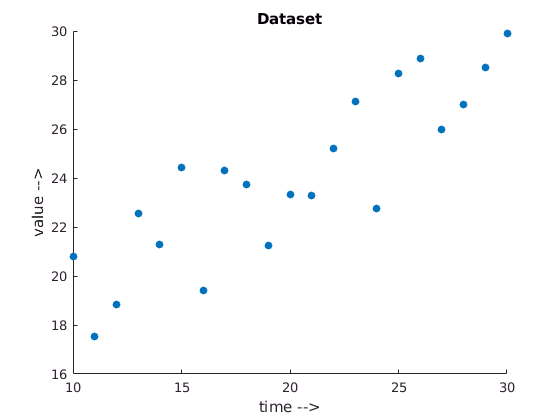

time = 10:30;
value = generateData(time, 7);
scatter(time, value, 'filled');
title('Dataset');
xlabel('time -->');
ylabel('value -->');

## Normalize the data and create feature vector

x = (time - mean(time)) / std(time);
X(:, 1) = 1;
X(:, 2) = x';
Y = (value - mean(value)) / std(value);

## Plotting the cost function

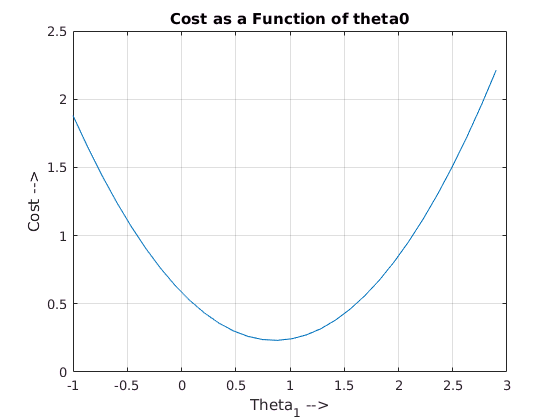

N = 30;
theta0 = linspace(-1.5, 1.5, N);
theta1 = linspace(-1, 2.9, N);
J = zeros(N);
for i = 1: N
    for j = 1: N
        theta = [theta0(i); theta1(j)];
        J(i, j) = costf(X, Y, theta);
    end
end

plot(theta1, J(20, :)); 
grid on;
title('Cost as a Function of theta0');
xlabel('Theta_1 -->');
ylabel('Cost -->');

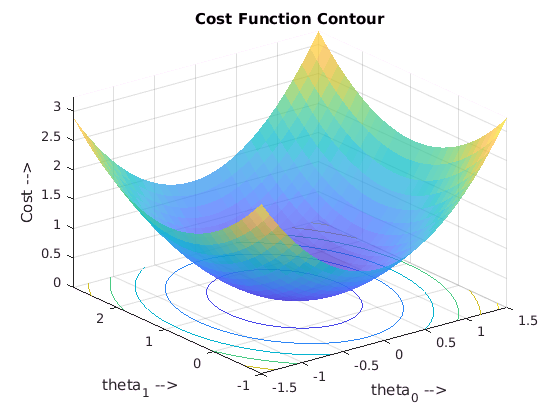


[T0, T1] = meshgrid(theta0, theta1);
surfc(T0, T1, J, 'FaceAlpha',0.7, 'EdgeColor', 'none');
title('Cost Function Contour');
xlabel('theta_0 -->');
ylabel('theta_1 -->');
zlabel('Cost -->');

## Gradient Descent

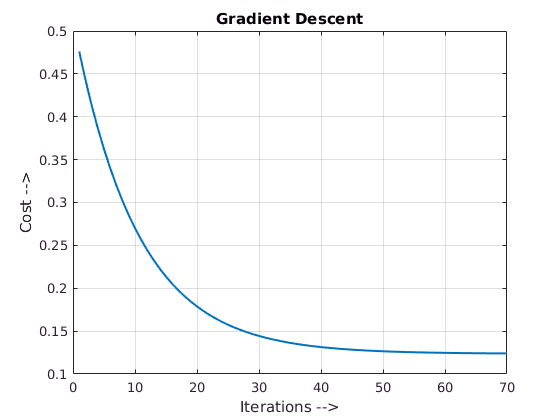

theta0 = 0;
theta1 = 0;
alpha = 0.05;
num_iter = 70;
m = length(Y);
J = zeros(1, num_iter);
for i = 1: num_iter
    theta = [theta0; theta1];
    h = hypothesis(X, theta);
    J(1, i) = costf(X, Y, theta);
    theta0 = theta0 - alpha * (1/m) * sum(h - Y);
    theta1 = theta1 - alpha * (1/m) * sum((h - Y) .* X(:, 2)');
end

plot(1: num_iter, J, 'LineWidth', 1.5);
grid on;
title('Gradient Descent');
xlabel('Iterations -->');
ylabel('Cost -->');

## Result

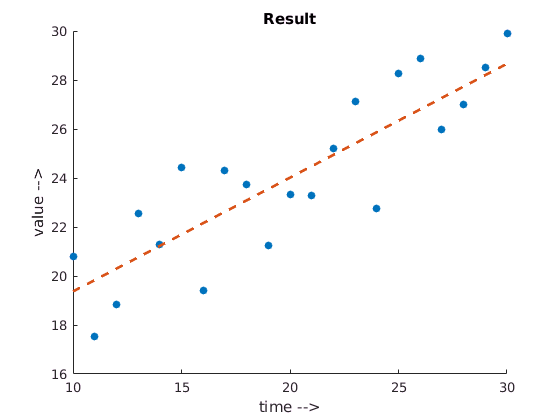

x = (x * std(time)) + mean(time);
Y = (Y * std(value)) + mean(value);
scatter(x, Y, 'filled');
hold on;
y = hypothesis(X, theta);
y = (y * std(value)) + mean(value);
plot(x, y, '--', 'LineWidth', 2); 
title('Result');
xlabel('time -->');
ylabel('value -->');